% Experiment-4: Bounding Box Image Area as Input: ResNet50 
% Author: Sujan Khanal
% ID: u3258630

close all;
clear variables;
clc;

rng(42, 'twister'); %% For reproducibility

%% STEP 1: Check and Reset GPU
if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device); % Reset any old data
else
    error('No GPU device found. Please ensure GPU is available.');
end

Found GPU:


    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      



## Read the training, validation and test partitions from the relevant


folder = "C:\Users\u3258630\Desktop\CVIA\u3258630_CVIA_Asgn1_Final\CUB_200_2011\";
trainingImageNames = readtable(fullfile(folder, "train200.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate200.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test200.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Read bounding box information from bounding_boxes.txt. The format is

boundingBoxes = readtable(folder + "bounding_boxes.txt", ...
    'ReadVariableNames', false);
boundingBoxes.Properties.VariableNames = {'index', 'x', 'y', 'w', 'h'};

% Map bounding box information to the respective image file name
train_image_box_map = returnMapping(trainingImageNames, boundingBoxes);
val_image_box_map = returnMapping(validationImageNames, boundingBoxes);
test_image_box_map = returnMapping(testImageNames, boundingBoxes);

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, train_image_box_map);
disp('Training set class samples:');

Training set class samples:


countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, val_image_box_map);
disp('Validation set class samples:');

Validation set class samples:


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames',   'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, test_image_box_map);
disp('Test set class samples:');

Test set class samples:


countEachLabel(testImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
labelsValidation = arrayDatastore(validationImageDS.Labels);
labelsTest = arrayDatastore(testImageDS.Labels);

cdsTraining = combine(trainingImageDS, labelsTraining);
cdsValidation = combine(validationImageDS, labelsValidation);
cdsTest = combine(testImageDS, labelsTest);

% Resize all images to a common width and height
targetSize = [224, 224];
cdsTraining = transform(cdsTraining, @(x) preprocessData(x,targetSize));
cdsValidation = transform(cdsValidation, @(x) preprocessData(x,targetSize));
cdsTest = transform(cdsTest, @(x) preprocessData(x,targetSize));

## Display a sample image from the datastore

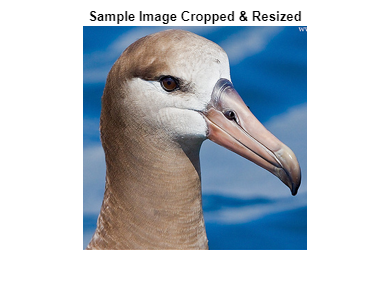

figure(1);
imshow(cdsTraining.read{1});
title('Sample Image Cropped & Resized');

## Load Pretrained ResNet-50 and Modify

net = resnet50;
lgraph = layerGraph(net);

numClasses = 200; % 200 classes full dataset

newLearnableLayer = fullyConnectedLayer(numClasses, 'Name', 'new_fc', ...
    'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10);

newClassLayer = classificationLayer('Name', 'new_classoutput');

lgraph = replaceLayer(lgraph, 'fc1000', newLearnableLayer);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassLayer);

## Set the training options

options = trainingOptions('sgdm', ...
    'MiniBatchSize', 16, ...
    'MaxEpochs', 20, ...
    'InitialLearnRate', 1e-4, ...
    'ValidationData', cdsValidation, ...
    'ValidationPatience', 5, ...
    'Shuffle', 'every-epoch', ...
    'ValidationFrequency', floor(numel(trainingImageDS.Files)/16), ...
    'Plots', 'training-progress', ...
    'Verbose', true, ...
    'ExecutionEnvironment', 'gpu', ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 7);

## Train the Network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:45 |        0.00% |        0.21% |       5.6543 |       5.6963 |      1.0000e-04 |
|       1 |          50 |       00:00:55 |        0.00% |              |       5.4248 |              |      1.0000e-04 |
|       1 |         100 |       00:01:06 |        6.25% |              |       4.9627 |              |      1.0000e-04 |
|       1 |         150 |       00:01:16 |        6.25% |              |       4.9172 |              |      1.0000

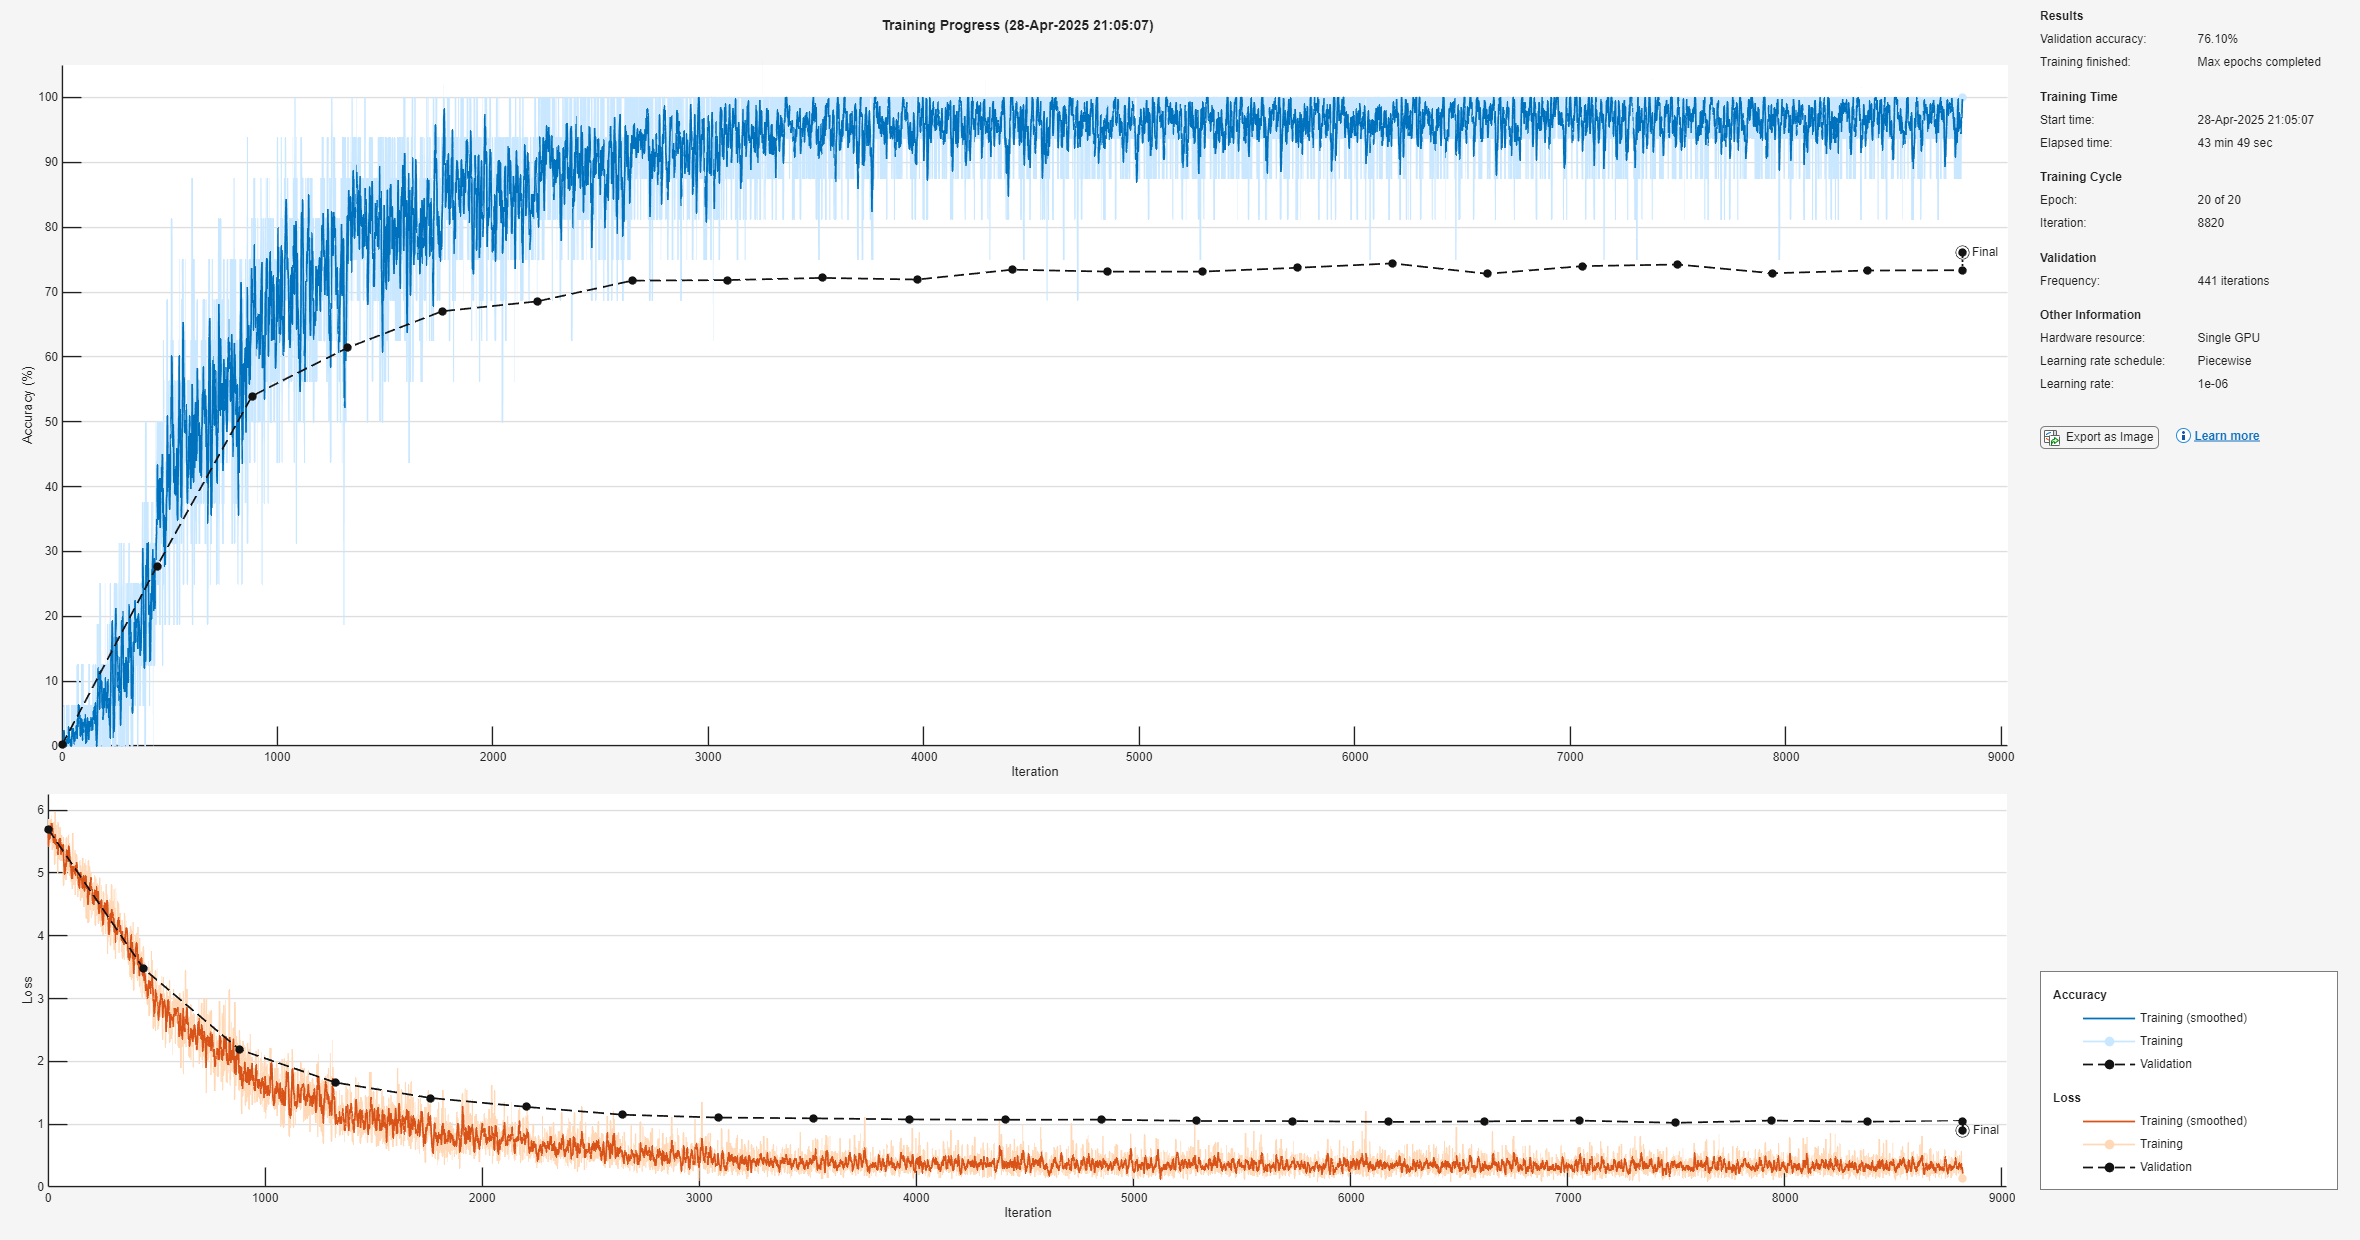

resnet50_cropped_trained = trainNetwork(cdsTraining, lgraph, options);

## Evaluate on Test Set

%% Evaluate on Test Set
YPred = classify(resnet50_cropped_trained, cdsTest, 'ExecutionEnvironment', 'gpu');
YTest = testImageDS.Labels;

YPredTrain = classify(resnet50_cropped_trained, cdsTraining, 'ExecutionEnvironment', 'gpu');
YTrain = trainingImageDS.Labels;

YPredValidation = classify(resnet50_cropped_trained, cdsValidation, 'ExecutionEnvironment', 'gpu');
YValidation = validationImageDS.Labels;

trainAccuracy = sum(YPredTrain == YTrain) / numel(YTrain);
validationAccuracy = sum(YPredValidation == YValidation) / numel(YValidation);
testAccuracy = sum(YPred == YTest) / numel(YTest);

disp(['Training Accuracy (ResNet-50 Bounding Box): ', num2str(trainAccuracy*100, '%.2f'), '%']);

Training Accuracy (ResNet-50 Bounding Box): 98.13%


disp(['Validation Accuracy (ResNet-50 Bounding Box): ', num2str(validationAccuracy*100, '%.2f'), '%']);

Validation Accuracy (ResNet-50 Bounding Box): 76.10%


disp(['Test Accuracy (ResNet-50 Bounding Box): ', num2str(testAccuracy*100, '%.2f'), '%']);

Test Accuracy (ResNet-50 Bounding Box): 75.55%


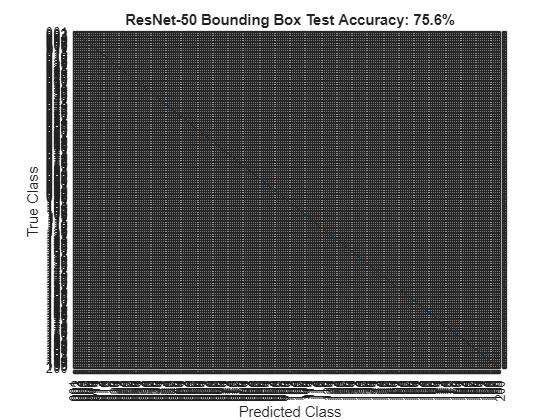


% Confusion Matrix
[m, order] = confusionmat(YTest, YPred);

figure;
cm = confusionchart(m, order, ...
    'ColumnSummary', 'column-normalized', ...
    'RowSummary', 'row-normalized');
title("ResNet-50 Bounding Box Test Accuracy: " + string(round(testAccuracy*100,1)) + "%");

## Compute classwise positive recognition rate

classwisePosRecog = zeros(height(order), 1);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog(iI) = round(100 * m(iI, iI) / samplesPerRow(iI), 1);
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog)

   91.7000
   83.3000
   81.8000
   83.3000
   66.7000
   75.0000
   91.7000
   66.7000
   50.0000
  100.0000
   41.7000
  100.0000
   91.7000
   91.7000
   90.9000
   81.8000
  100.0000
  100.0000
   83.3000
   75.0000
   83.3000
   72.7000
   58.3000
   90.0000
   75.0000
   66.7000
   33.3000
  100.0000
   33.3000
   16.7000
   83.3000
   60.0000
   58.3000
   83.3000
  100.0000
   91.7000
   33.3000
   50.0000
   25.0000
   66.7000
   66.7000
  100.0000
   41.7000
   75.0000
   58.3000
   75.0000
  100.0000
  100.0000
   66.7000
   66.7000
   91.7000
   83.3000
  100.0000
   58.3000
   91.7000
   83.3000
   91.7000
   81.8000
   25.0000
   33.3000
  100.0000
   41.7000
  100.0000
   66.7000
   50.0000
   41.7000
   75.0000
   75.0000
   83.3000
  100.0000
   33.3000
   58.3000
   91.7000
   91.7000
  100.0000
  100.0000
   83.3000
   66.7000
   91.7000
   66.7000
   83.3000
   83.3000
  100.0000
   83.3000
   91.7000
   91.7000
  100.0000
  100.0000
   91.7000
   91.7000
   83.3000

## Helper function for resizing images in transform

function data_out = preprocessData(data, targetSize)
try
    data_out{1} = imresize(data{1}, targetSize(1:2)); % Resize images
    data_out{2} = data{2};  % Keep labels as they are
catch e
    % This is for debugging
    disp(e)
end
end

## Helper function mapping image names to bounding boxes and vice versa

function image_box_map = returnMapping(ImageNames, boundingBoxes)
image_box_map = containers.Map;
for i = 1:size(ImageNames, 1)
    fn = ImageNames{i,2}{1};
    fn = split(fn, "\");
    fn = split(fn, "/");
    image_box_map(fn{end}) = [boundingBoxes{ImageNames{i,1}, 2:5}];
end
end




